## Assignment 2: Time Frequency Analysis and ERSP Plotting

## 1. Time-frequency Analysis:

Please refer to the link below: [https://eeglab.org/tutorials/08_Plot_data/Time-Frequency_decomposition.html](https://eeglab.org/tutorials/08_Plot_data/Time-Frequency_decomposition.html)

using data in assigment 1

% Using IClab to classify data after ICA.
% line noise channel : 2 12 14 18 19 27 29 31
% other : 1 3 5 7 8 17 22 24 28 30 32
% eye : 10 11 

[ALLEEG EEG CURRENTSET ALLCOM] = eeglab;

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\USER\eeg_options.m
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" v3.8.1 to the path
--------------------------------------------------------------------------------------------------------------------------------------------
%Equivalent command:
 erplab_running_version(   'tooltype', 'ERPLAB' 'version', '10.0' );
--------------------------------------------------------------------------------------------------------------------------------------------
Go back to ERPLAB menu

EEGLAB: adding "ERPLAB" v10.0 (see >> help eegplugin_erplab)
EEGLAB: adding "Fileio" v20230819 to the path - new version 20230822 available
EEGLAB: adding "ICLabel" v1.4 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.8 (see >> help eegplugin_clean_rawdata)
EEGLAB: adding "dipf

EEG = pop_loadset('filename','eeglab_data.set','filepath','C:\\Users\\USER\\Documents\\MATLAB\\eeglab\\sample_data\\');

pop_loadset(): loading file C:\Users\USER\Documents\MATLAB\eeglab\sample_data\eeglab_data.set ...
Reading float file 'C:\Users\USER\Documents\MATLAB\eeglab\sample_data\eeglab_data.fdt'...


[ALLEEG, EEG, CURRENTSET] = eeg_store( ALLEEG, EEG, 0 );

Creating a new ALLEEG dataset 1


EEG = pop_epoch( EEG, {  'square'  }, [-1  2], 'newname', 'Continuous EEG Data epochs', 'epochinfo', 'yes');

pop_epoch():80 epochs selected
Epoching...
pop_epoch():80 epochs generated
pop_epoch(): checking epochs for data discontinuity


EEG = pop_rmbase( EEG, [],[]);

pop_rmbase(): Removing baseline...


EEG = pop_runica(EEG, 'icatype', 'runica', 'extended',1,'interrupt','on');

Attempting to convert data matrix to double precision for more accurate ICA results.

Input data size [32,30720] = 32 channels, 30720 frames/nFinding 32 ICA components using extended ICA.
Kurtosis will be calculated initially every 1 blocks using 6000 data points.
Decomposing 30 frames per ICA weight ((1024)^2 = 30720 weights, Initial learning rate will be 0.001, block size 52.
Learning rate will be multiplied by 0.98 whenever angledelta >= 60 deg.
More than 32 channels: default stopping weight change 1E-7
Training will end when wchange < 1e-06 or after 512 steps.
Online bias adjustment will be used.
Removing mean of each channel ...
Final training data range: -278.247 to 568.906
Computing the sphering matrix...
Starting weights are the identity matrix ...
Sphering the data ...
Beginning ICA training ... first training step may be slow ...


step 1 - lrate 0.001000, wchange 13.31708295, angledelta  0.0 deg
step 2 - lrate 0.001000, wchange 0.28784625, angledelta  0.0 deg
step 3 - lrate 0.001000, wchange 0.22927089, angledelta 74.3 deg
step 4 - lrate 0.000980, wchange 0.15706899, angledelta 95.2 deg
step 5 - lrate 0.000960, wchange 0.13174631, angledelta 96.8 deg
step 6 - lrate 0.000941, wchange 0.13025499, angledelta 98.6 deg
step 7 - lrate 0.000922, wchange 0.12919664, angledelta 98.4 deg
step 8 - lrate 0.000904, wchange 0.11018205, angledelta 107.4 deg
step 9 - lrate 0.000886, wchange 0.09141735, angledelta 101.2 deg
step 10 - lrate 0.000868, wchange 0.09206466, angledelta 99.1 deg
step 11 - lrate 0.000851, wchange 0.09197025, angledelta 109.7 deg
step 12 - lrate 0.000834, wchange 0.09594502, angledelta 110.5 deg
step 13 - lrate 0.000817, wchange 0.15422095, angledelta 112.5 deg
step 14 - lrate 0.000801, wchange 0.15346114, angledelta 130.3 deg
step 15 - lrate 0.000785, wchange 0.09085984, angledelta 115.7 deg
step 16 - l

[ALLEEG, EEG, CURRENTSET] = eeg_store(ALLEEG, EEG, CURRENTSET);

Scaling components to RMS microvolt


EEG = pop_iclabel(EEG, 'default');

ICLabel: extracting features...
Scaling components to RMS microvolt
Recomputing ICA activations
ICLabel: calculating labels...
Failed to run ICLabel. Trying to compile MEX-files.
MEX-file compilation failed. Further instructions on compiling the MEX-files can be found at http://www.vlfeat.org/matconvnet/install/. Further, you may contact Luca Pion-Tonachini at lpionton@ucsd.edu for help. If you solve this issue without help, please consider emailing Luca as the compiled files will likely be useful to other EEGLAB users with similar computers as yourself.


ICLabel: saving results...


[ALLEEG, EEG, CURRENTSET] = eeg_store(ALLEEG, EEG, CURRENTSET);

Scaling components to RMS microvolt


EEG = pop_subcomp( EEG, [1   2   3   5   7   8  10  11  12  14  17  18  19  22  24  27  28  29  30  31  32], 0);

Computing projection and removing 21 components ....


[ALLEEG EEG CURRENTSET] = pop_newset(ALLEEG, EEG, 1,'gui','off'); 

Creating a new ALLEEG dataset 2


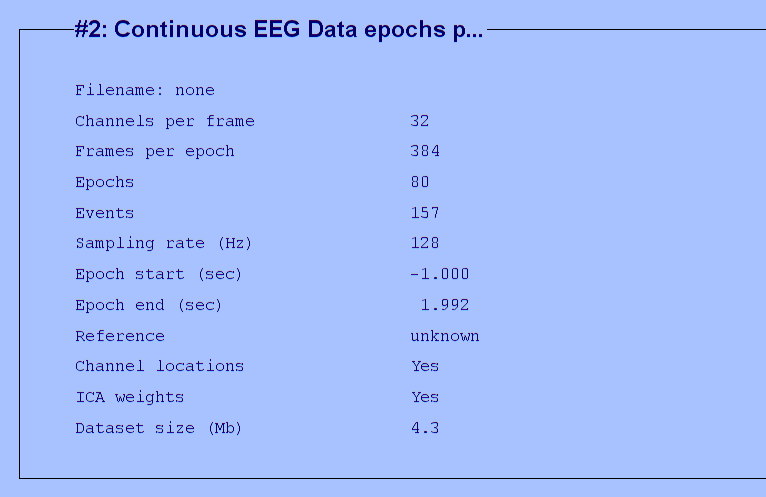

Value of timesout must be <= frames-winsize, timeout adjusted to 193
Computing Event-Related Spectral Perturbation (ERSP) and
  Inter-Trial Phase Coherence (ITC) images based on 80 trials
  of 257 frames sampled at 128 Hz.
Each trial contains samples from 0 ms before to
  238305 ms after the timelocking event.
  Image frequency direction: normal
Using 3 cycles at lowest frequency to 5 at highest.
Value of 'timesout' must be <= frame-winsize, 'timesout' adjusted to 186
Generating 186 time points (33046.2 to 205258.8 ms)
Distribution of data point for time/freq decomposition is perfectly uniform
The window size used is 71 samples (554.688 ms) wide.
Estimating 23 linear-spaced frequencies from 6.0 Hz to 50.0 Hz.
Processing time point (of 186): 10 20 30 40 50 60 70 80 90 100 110 120
 130 140 150 160 170 180
Computing the mean baseline spectrum


Note: Add output variables to command line call in history to
      retrieve results and use the tftopo function to replot them


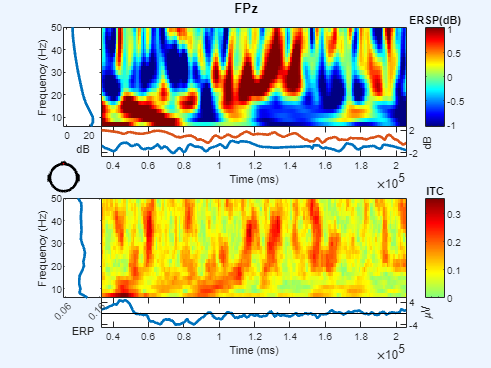

figure; pop_newtimef( EEG, 1, 1, [0  238305], [3         0.8] , 'topovec', 1, 'elocs', EEG.chanlocs, 'chaninfo', EEG.chaninfo, 'caption', 'FPz', 'baseline',[0], 'plotphase', 'off', 'padratio', 1);